clear all;

addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

load('./completeData/human_data.mat');

meanhumans_cortdist_rh = mean(human_data.dist_from_v1_rh,2,'omitnan');
meanhumans_cortdist_lh = mean(human_data.dist_from_v1_lh,2,'omitnan');

meanhumans_cortdist_rh1234=[];
meanhumans_cortdist_rh1234(1)=0;
meanhumans_cortdist_rh1234(2)=[meanhumans_cortdist_rh(3)+meanhumans_cortdist_rh(4)]/2;
meanhumans_cortdist_rh1234(3)=[meanhumans_cortdist_rh(5)+meanhumans_cortdist_rh(6)]/2;
meanhumans_cortdist_rh1234=[meanhumans_cortdist_rh1234,meanhumans_cortdist_rh(7:end)'];

meanhumans_cortdist_lh1234=[];
meanhumans_cortdist_lh1234(1)=0;
meanhumans_cortdist_lh1234(2)=[meanhumans_cortdist_lh(3)+meanhumans_cortdist_lh(4)]/2;
meanhumans_cortdist_lh1234(3)=[meanhumans_cortdist_lh(5)+meanhumans_cortdist_lh(6)]/2;
meanhumans_cortdist_lh1234=[meanhumans_cortdist_lh1234,meanhumans_cortdist_lh(7:end)'];

meanhumans_cortdist1234=[meanhumans_cortdist_lh1234+meanhumans_cortdist_lh1234]/2;

% Human Labels
human_labels = [{'V1', 'V2', 'V3'},human_data.labels{7:end}];
disp(human_labels)

  Columns 1 through 13

    {'V1'}    {'V2'}    {'V3'}    {'hV4'}    {'VO1'}    {'VO2'}    {'PHC1'}    {'PHC2'}    {'V3A'}    {'V3B'}    {'LO1'}    {'LO2'}    {'TO1'}

  Columns 14 through 21

    {'TO2'}    {'IPS0'}    {'IPS1'}    {'IPS2'}    {'IPS3'}    {'IPS4'}    {'IPS5'}    {'SPL1'}



human_areadistfromV1 = human_data.areadistfromV1;
human_fellemanhierarchy = human_data.fellemanhierarchy;

surfacearea_total_prob = human_data.total_size_prob;
surfacearea_total = human_data.total_size;

% Make 0 sum ROIs -> NaN
for i = 1:2
    human_data.surfacearea_smoothwm_prob{i}(human_data.surfacearea_smoothwm_prob{i}==0)=nan;
    human_data.surfacearea_pial_prob{i}(human_data.surfacearea_pial_prob{i}==0)=nan;
    human_data.surfacearea_smoothwm{i}(human_data.surfacearea_smoothwm{i}==0)=nan;
    human_data.surfacearea_pial{i}(human_data.surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
human_surfacearea_avg_prob = cellfun(@(x,y) (x+y)/2, human_data.surfacearea_smoothwm_prob, human_data.surfacearea_pial_prob,'UniformOutput',false);
human_surfacearea_avg = cellfun(@(x,y) (x+y)/2, human_data.surfacearea_smoothwm, human_data.surfacearea_pial,'UniformOutput',false);

human_bothhemi_SA_prob = [human_surfacearea_avg_prob{1} + human_surfacearea_avg_prob{2}];
human_bothhemi_SA = [human_surfacearea_avg{1} + human_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(1:2,:),1);
V2_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(3:4,:),1);
V3_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(5:6,:),1);
V1_sumhemis_sumvd = sum(human_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(human_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(human_bothhemi_SA(5:6,:),1);

SA_sumvd_human_prob = [V1_sumhemis_sumvd_prob;V2_sumhemis_sumvd_prob;...
    V3_sumhemis_sumvd_prob;human_bothhemi_SA_prob(7:end,:)];
SA_sumvd_human = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;human_bothhemi_SA(7:end,:)];

human_bothhemi_SA_prob = [human_surfacearea_avg_prob{1} human_surfacearea_avg_prob{2}];
human_bothhemi_SA = [human_surfacearea_avg{1} human_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(1:2,:),1);
V2_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(3:4,:),1);
V3_sumhemis_sumvd_prob = sum(human_bothhemi_SA_prob(5:6,:),1);
V1_sumhemis_sumvd = sum(human_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(human_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(human_bothhemi_SA(5:6,:),1);

SA_catvd_human_prob = [V1_sumhemis_sumvd_prob;V2_sumhemis_sumvd_prob;...
    V3_sumhemis_sumvd_prob;human_bothhemi_SA_prob(7:end,:)];
SA_catvd_human = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;human_bothhemi_SA(7:end,:)];

surfacearea_LH_human = human_data.total_size(:,2);
surfacearea_RH_human = human_data.total_size(:,1);
total_catvd_human_prob = [surfacearea_total_prob(:,1);surfacearea_total_prob(:,2)];
surfacearea_LH_human_prob = human_data.total_size(:,2);
surfacearea_RH_human_prob = human_data.total_size(:,1);
total_catvd_human = [surfacearea_total(:,1);surfacearea_total(:,2)];

load('./completeData/neo_data.mat');

% Make 0 sum ROIs -> NaN
for i = 1:2
    neo_data.surfacearea_smoothwm{i}(neo_data.surfacearea_smoothwm{i}==0)=nan;
    neo_data.surfacearea_pial{i}(neo_data.surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
neo_surfacearea_avg = cellfun(@(x,y) (x+y)/2, neo_data.surfacearea_smoothwm, neo_data.surfacearea_pial,'UniformOutput',false);

neo_sumhemi_SA = [neo_surfacearea_avg{1} + neo_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(neo_sumhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(neo_sumhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(neo_sumhemi_SA(5:6,:),1);

SA_sumvd_neo = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;neo_sumhemi_SA(7:end,:)];

neo_bothhemi_SA = [neo_surfacearea_avg{1} neo_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(neo_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(neo_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(neo_bothhemi_SA(5:6,:),1);

SA_catvd_neo = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;neo_bothhemi_SA(7:end,:)];

neo_bothhemi_WM = [neo_data.surfacearea_smoothwm{1} neo_data.surfacearea_smoothwm{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(neo_bothhemi_WM(1:2,:),1);
V2_sumhemis_sumvd = sum(neo_bothhemi_WM(3:4,:),1);
V3_sumhemis_sumvd = sum(neo_bothhemi_WM(5:6,:),1);

WM_catvd_neo = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;neo_bothhemi_WM(7:end,:)];

neo_bothhemi_pial = [neo_data.surfacearea_pial{1} neo_data.surfacearea_pial{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(neo_bothhemi_pial(1:2,:),1);
V2_sumhemis_sumvd = sum(neo_bothhemi_pial(3:4,:),1);
V3_sumhemis_sumvd = sum(neo_bothhemi_pial(5:6,:),1);

pial_catvd_neo = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;neo_bothhemi_pial(7:end,:)];

surfacearea_LH_neo = mean(neo_data.allsubjs_totalhemisphere_lh,2);
surfacearea_RH_neo = mean(neo_data.allsubjs_totalhemisphere_rh,2);
total_catvd_neo = [surfacearea_RH_neo;surfacearea_LH_neo];

load('./completeData/monkey_data.mat');

% Make 0 sum ROIs -> NaN
for i = 1:2
    monkey_data.retino_surfacearea_smoothwm{i}(monkey_data.retino_surfacearea_smoothwm{i}==0)=nan;
    monkey_data.retino_surfacearea_pial{i}(monkey_data.retino_surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
monk_surfacearea_avg = cellfun(@(x,y) (x+y)/2, monkey_data.retino_surfacearea_smoothwm, monkey_data.retino_surfacearea_pial,'UniformOutput',false);

monk_sumhemi_SA = [monk_surfacearea_avg{1} + monk_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(monk_sumhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(monk_sumhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(monk_sumhemi_SA(5:6,:),1);
V4_sumhemis_sumvd = sum(monk_sumhemi_SA(7:8,:),1);
V4A_sumhemis_sumvd = sum(monk_sumhemi_SA(9:10,:),1);

SA_sumvd_monk = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;V4_sumhemis_sumvd;V4A_sumhemis_sumvd;monk_sumhemi_SA(11:end,:)];

monk_bothhemi_SA = [monk_surfacearea_avg{1} monk_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(monk_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(monk_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(monk_bothhemi_SA(5:6,:),1);
V4_sumhemis_sumvd = sum(monk_bothhemi_SA(7:8,:),1);
V4A_sumhemis_sumvd = sum(monk_bothhemi_SA(9:10,:),1);

SA_catvd_monk = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;V4_sumhemis_sumvd;V4A_sumhemis_sumvd;monk_bothhemi_SA(11:end,:)];

monk_bothhemi_WM = [monkey_data.retino_surfacearea_smoothwm{1} monkey_data.retino_surfacearea_smoothwm{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(monk_bothhemi_WM(1:2,:),1);
V2_sumhemis_sumvd = sum(monk_bothhemi_WM(3:4,:),1);
V3_sumhemis_sumvd = sum(monk_bothhemi_WM(5:6,:),1);

WM_catvd_monk = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;monk_bothhemi_WM(7:end,:)];

monk_bothhemi_pial = [monkey_data.retino_surfacearea_pial{1} monkey_data.retino_surfacearea_pial{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(monk_bothhemi_pial(1:2,:),1);
V2_sumhemis_sumvd = sum(monk_bothhemi_pial(3:4,:),1);
V3_sumhemis_sumvd = sum(monk_bothhemi_pial(5:6,:),1);

pial_catvd_monk = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;monk_bothhemi_pial(7:end,:)];

surfacearea_LH_monk = monkey_data.total_size(:,2);
surfacearea_RH_monk = monkey_data.total_size(:,1);
total_catvd_monk = [surfacearea_RH_monk;surfacearea_LH_monk];

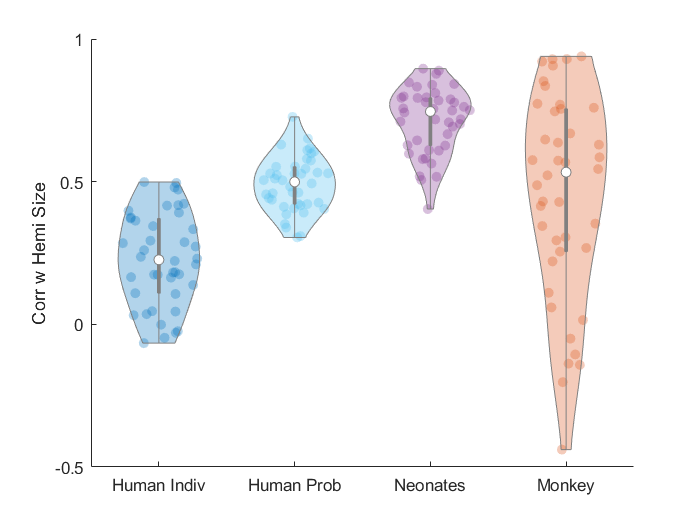

all_dat = {SA_catvd_human,SA_catvd_human_prob,SA_catvd_neo,SA_catvd_monk};
all_hemi_dat_LH = {surfacearea_LH_human,surfacearea_LH_human_prob,surfacearea_LH_neo,surfacearea_LH_monk};
all_hemi_dat_RH = {surfacearea_RH_human,surfacearea_RH_human_prob,surfacearea_RH_neo,surfacearea_RH_monk};

RH_corr = {};
LH_corr = {};
all_corr = zeros(length(all_dat),size(all_dat{i},1)*2);
for i = 1:length(all_dat)
    for j = 1:size(all_dat{i},1)
        nSubj = size(all_dat{i},2)/2;
        includeRH = find(~isnan(all_dat{i}(j,1:nSubj)));
        includeLH = find(~isnan(all_dat{i}(j,nSubj+1:end)));
        RH_corr{i}(j) = corr2(all_dat{i}(j,includeRH),all_hemi_dat_RH{i}(includeRH)');
        LH_corr{i}(j) = corr2(all_dat{i}(j,includeLH+nSubj),all_hemi_dat_LH{i}(includeLH)');
    end
    all_corr(i,:) = [RH_corr{i} LH_corr{i}];
end

figure;hold on;
violinplot(all_corr');
xticks(1:4)
xticklabels({'Human Indiv','Human Prob','Neonates','Monkey'})
ylabel('Corr w Hemi Size')


[h1,p1] = kstest2(all_corr(1,:),all_corr(2,:))

h1 = logical
   1


p1 = 1.1212e-09

[h2,p2] = kstest2(all_corr(1,:),all_corr(3,:))

h2 = logical
   1


p2 = 6.4462e-19

[h3,p3] = kstest2(all_corr(2,:),all_corr(3,:))

h3 = logical
   1


p3 = 1.1212e-09

[h4,p4] = kstest2(all_corr(1,:),all_corr(4,:))

h4 = logical
   1


p4 = 9.4803e-06

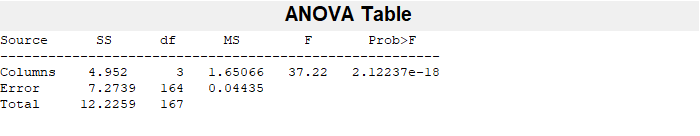


[p,tbl,stats] = anova1(all_corr');

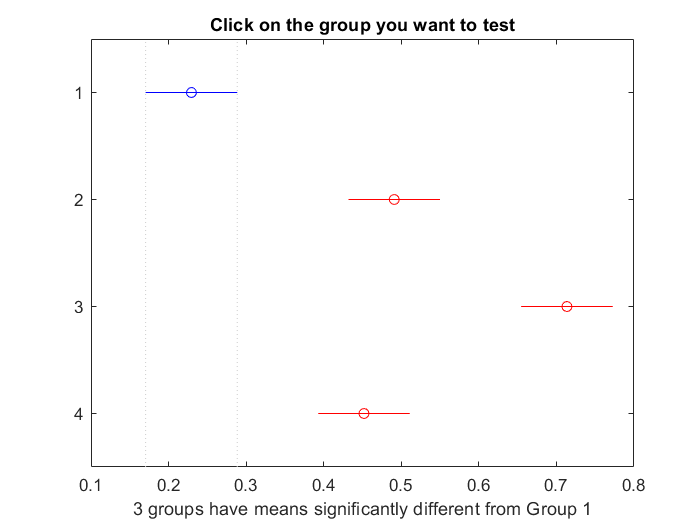

results = multcompare(stats);

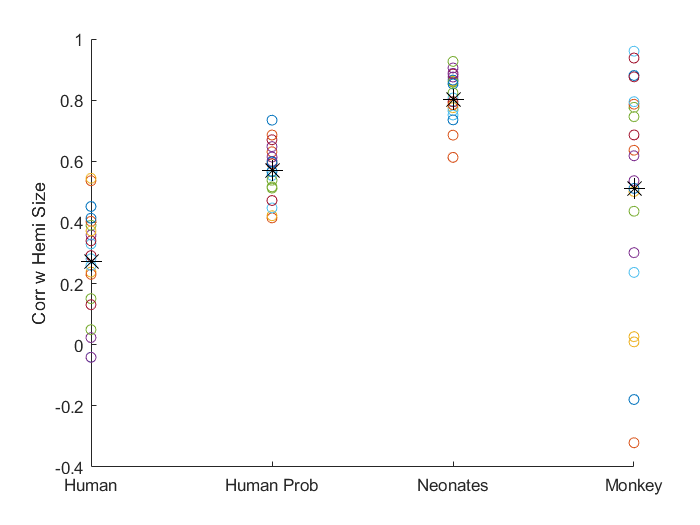

all_dat = {SA_sumvd_human,SA_sumvd_human_prob,SA_sumvd_neo,SA_sumvd_monk};
all_hemi_dat = {surfacearea_LH_human+surfacearea_RH_human,surfacearea_LH_human_prob+surfacearea_RH_human_prob,surfacearea_LH_neo+surfacearea_RH_neo,surfacearea_LH_monk+surfacearea_RH_monk};

all_corr = {};
for i = 1:length(all_dat)
    for j = 1:size(all_dat{i},1)
        include = find(~isnan(all_dat{i}(j,:)));
        all_corr{i}(j) = corr2(all_dat{i}(j,include),all_hemi_dat{i}(include)');
    end
end

figure;hold on;
for i = 1:length(all_dat)
    plot(i,all_corr{i},'o')
    plot(i,mean(all_corr{i},'all'),'k*','MarkerSize',12)
end
xticks(1:4)
xticklabels({'Human','Human Prob','Neonates','Monkey'})
ylabel('Corr w Hemi Size')


[h1,p1] = kstest2(all_corr{1},all_corr{2})

h1 = logical
   1


p1 = 8.8857e-08

[h2,p2] = kstest2(all_corr{2},all_corr{3})

h2 = logical
   1


p2 = 8.8857e-08

[h3,p3] = kstest2(all_corr{1},all_corr{3})

h3 = logical
   1


p3 = 1.9664e-10

[h4,p4] = kstest2(all_corr{1},all_corr{4})

h4 = logical
   1


p4 = 0.0011

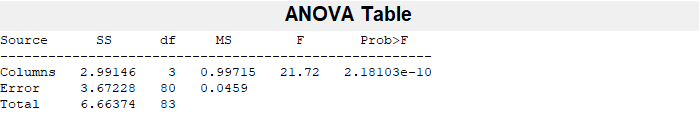


[p,tbl,stats] = anova1([all_corr{1}' all_corr{2}' all_corr{3}' all_corr{4}']);

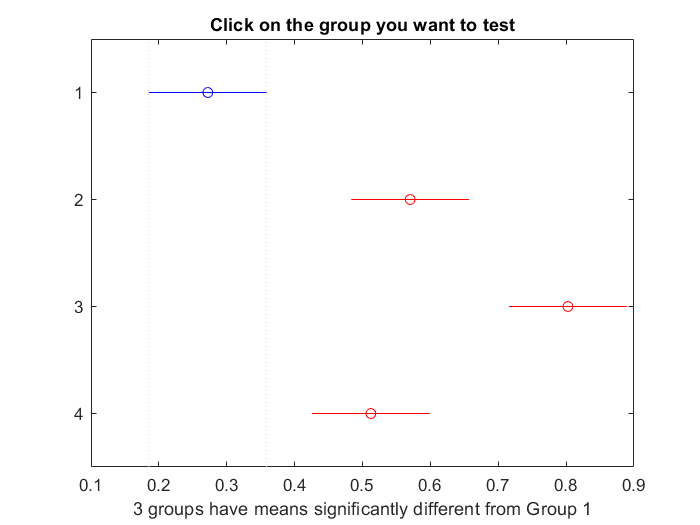

results = multcompare(stats);


% see if humans are different than human prob and if human prob is diff than neonates using KS test
% prob get rid of monkeys
% use violin plot maybe
% can also try collapsing across hemispheres